# Chapter 1, Section 2 (Part 5)

The goal of this activity is to solve some systems representing applications.

# Example #1:

Consider the following system. 


$$\begin{array}{rcl}
x+2z&=&a\\
x+y+3z&=&b\\
y+z&=&c
\end{array}$$


Determine the values of $a$, $b$, and $c$ for which the system is consistent.

**Solution:** Set up the augmented matrix and highlight the leading term in the first row.


$$\pmatrix{[1]&0&2&a\cr 1&1&3&b\cr 0&1&1&c}$$


Use the leading term in the first row to zero out the entries in the column below it.


$$\pmatrix{[1]&0&2&a\cr 1&1&3&b\cr 0&1&1&c}\ \matrix{~\cr R_2-R1\cr ~}\qquad\longrightarrow\qquad\pmatrix{1&0&2&a\cr 0&1&1&b-a\cr 0&1&1&c}$$


We can check this step with Matlab's Symbolic Toolbox.

syms a b c
A=[1 0 2 a;1 1 3 b;0 1 1 c];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2-r1;r3]

$$A = \left(\begin{array}{cccc} 1 & 0 & 2 & a\\ 0 & 1 & 1 & b-a\\ 0 & 1 & 1 & c \end{array}\right)$$

Correct. Now we'll highlight the leading term in the second row and use it zero out all terms below it.


$$\pmatrix{1&0&2&a\cr 0&[1]&1&b-a\cr 0&1&1&c}\ \matrix{~\cr ~\cr R_3-R_2}\qquad\longrightarrow\qquad\pmatrix{1&0&2&a\cr 0&1&1&b-a\cr 0&0&0&a-b+c}$$


We'll also check this step with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2;r3-r2]

$$A = \left(\begin{array}{cccc} 1 & 0 & 2 & a\\ 0 & 1 & 1 & b-a\\ 0 & 0 & 0 & a-b+c \end{array}\right)$$

We've done this correctly. The third row is equivalent to the equation


$$0x+0y+0z=a-b+c$$


which will have an infinite number of solutions (because $z$ is a free variable) provided $a-b+c=0$. Therefore, any point $(a,b,c)$ in the plane $a-b+c=0$ has a solution. For example, let's choose $(a,b,c)=(2,1,-1)$. Note that this point satisfies $a-b+c=0$.

a=2;b=1;c=-1;
a-b+c

ans = 0

Recall that our original system of equations was:


$$\begin{array}{rcl}
x+2z&=&a\\
x+y+3z&=&b\\
y+z&=&c
\end{array}$$


Now we will substitute $a=2$, $b=1$, and $c=-1$ and see if the system has a solution.


$$\begin{array}{rcl}
x+2z&=&2\\
x+y+3z&=&1\\
y+z&=&-1
\end{array}$$


Write the augmented matrix.


$$\pmatrix{1& 0& 2& 2\cr 1& 1& 3& 1\cr 0& 1& 1& -1}$$


Let's enter this in Matlab and use Matlab's rref command to put it in reduced row echelon form.

A=[1 0 2 2;1 1 3 1;0 1 1 -1];
rref(A)

ans =      1     0     2     2
     0     1     1    -1
     0     0     0     0


We've highlighted the pivots and reminded ourselves which variable each column represents and labeled the variables as pivots or free variables.


$$\begin{array}{rcl}
\matrix{x & \ y &\ z & ~~~~}\\
\pmatrix{[1]&0&2&2\cr 0&[1]&1&-1\cr 0&0&0&0}\\
\matrix{p&\ p&\ f&~~~~}
\end{array}$$


This represents the following system.


$$\begin{array}{rcl}
x+2z&=&2\\
y+z&=&-1\\
z&=&\text{free}
\end{array}$$


Now, the rule is to solve for the pivot variables in terms of the free variables. Therfore, 


$$\begin{array}{rcl}
x&=&-2z+2\\
y&=&-z-1\\
z&=&\text{free}
\end{array}$$


So, this system has an infinite number of solutions. Let's choose $z=0$. Then, we have the following solution:


$$(x,y,z)=(2,-1,0)$$


If we substitute these values into our system


$$\begin{array}{rcl}
x+2z&=&2\\
x+y+3z&=&1\\
y+z&=&-1
\end{array}$$


we get:


$$\begin{array}{rcl}
2+2(-0)&=&2\\
2+(-1)+3(0)&=&1\\
-1+0&=&-1
\end{array}$$


Note that this checks. We can also check this with Matlab. Insert $(x,y,z)=(2,-1,0)$ and see what we get.

x=2;y=-1;z=0;
[x+2*z,x+y+3*z,y+z]

ans =      2     1    -1


These are the right-hand sides of the equations in our system, so we are correct.

# Visualize Our Answer

In Example #1, we showed that the system 


$$\begin{array}{rcl}
x+2z&=&a\\
x+y+3z&=&b\\
y+z&=&c
\end{array}$$


has a solution if and only if $a-b+c=0$. Now, $a-b+c=0$ is the equation of a plane.


$$\begin{array}{rcl}
a-b+c&=&0\\
a&=&b-c
\end{array}$$


Now, $b$ and $c$ are free variables, so we will let $b=s$ and $c=t$, where $s,t\in \mathbb R$.


$$\begin{array}{rcl}
a&=&s-t\\
b&=&s\\
c&=&t
\end{array}$$


Now we will plot this plane.

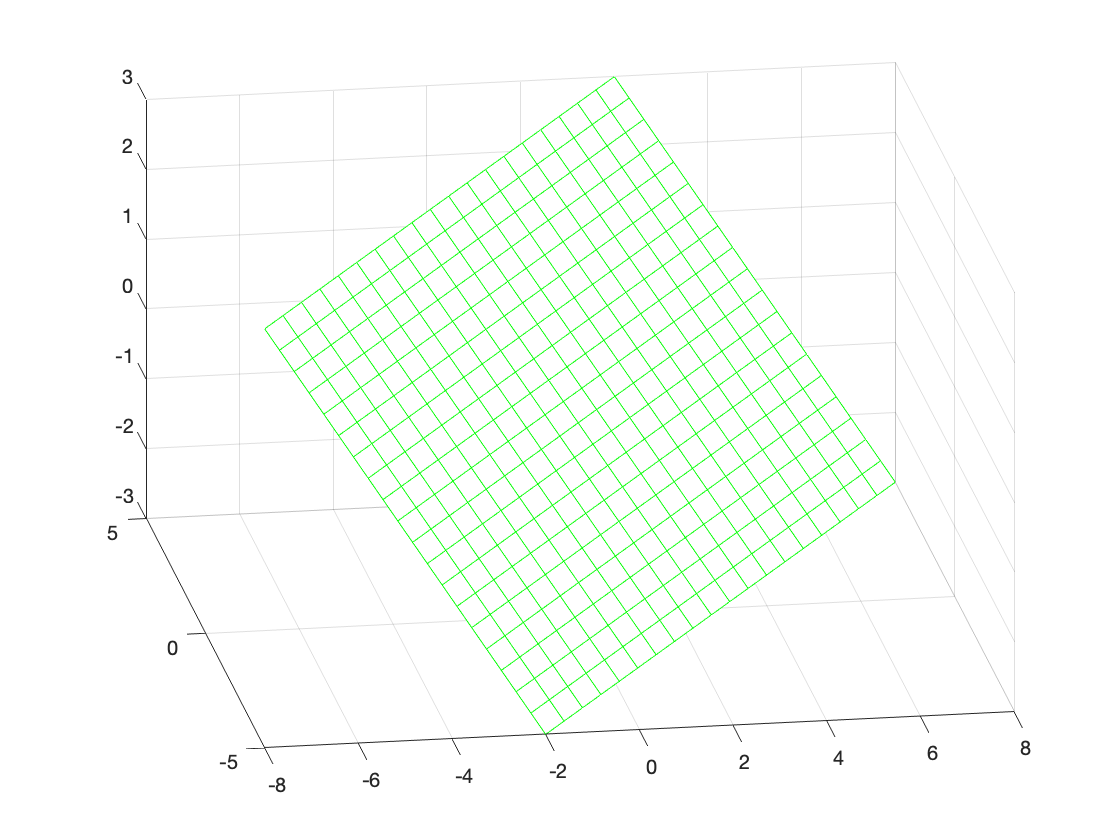

figure
s=linspace(-5,5,20);
t=linspace(-3,3,20);
[S,T]=meshgrid(s,t);
X=S-T;
Y=S;
Z=T;
mesh(X,Y,Z,'EdgeColor','g')
view(-9,29)

Now, we enter our coefficient matrix, which is:


$$A=\pmatrix{[1]&0&2\cr 1&1&3\cr 0&1&1}$$


A=[1 0 2;1 1 3;0 1 1]

A =      1     0     2
     1     1     3
     0     1     1


Matlab's rand(m,n) creates a random $m\times n$ matrix of random numbers between 0 and 1 inclusive. Let's create a random $3\times 5$ matrix filled with random numbers between 0 and 1.

rand(3,5)

ans =     0.1626    0.1431    0.0705    0.7337    0.5608
    0.7649    0.8277    0.4779    0.8162    0.3465
    0.9833    0.8811    0.7388    0.5335    0.5508


 Let's create a random $3\times 5$ matrix filled with random numbers between 0 and 2.

2*rand(3,5)

ans =     0.0422    1.6726    0.1899    0.0327    1.4436
    1.4735    0.0662    1.7018    0.2584    0.0741
    1.6679    1.8243    1.0444    1.1863    0.3523


 Let's create a random $3\times 5$ matrix filled with random numbers between -1 and 1.

1-2*rand(3,5)

ans =     0.5351   -0.1788   -0.9679   -0.1935   -0.3675
   -0.4300   -0.7459    0.4801    0.4413   -0.6226
   -0.5412    0.0920   -0.3813    0.4416    0.8475


 Let's create a random $3\times 100$ matrix filled with random numbers between -1 and 1.

pts=1-2*rand(3,100)

pts =     0.2613   -0.9875    0.3231   -0.5114    0.2492    0.3521    0.3432    0.8529   -0.1353    0.1528    0.4184    0.7551    0.7862   -0.3670   -0.8836    0.1511   -0.6043   -0.8133   -0.0905    0.1569   -0.9678   -0.9981    0.7908    0.2468    0.5141    0.2601    0.4249    0.0438    0.4200   -0.7296   -0.9200   -0.9583    0.6532   -0.7011   -0.2562   -0.7612    0.5819    0.8191   -0.5509    0.4333    0.7115   -0.7006    0.8872   -0.9892    0.4570   -0.0308    0.5697    0.6353   -0.9491   -0.2152
   -0.6125    0.1489    0.0907   -0.9848   -0.4173   -0.6180    0.0760   -0.0104    0.9450   -0.2906    0.1390    0.7391    0.8139   -0.0830   -0.2750    0.5033   -0.5233   -0.3113    0.3894    0.2649    0.8923    0.1700   -0.1792   -0.8727   -0.4842    0.0144    0.4148   -0.8638   -0.9162   -0.0465   -0.3444    0.4103    0.9982    0.3272    0.1992   -0.2382    0.4834   -0.1916   -0.2848    0.7283   -0.7121    0.5344   -0.4153   -0.0334    0.2435    0.0621   -0.2903   -0.7354    0.4290   

Now, we will multiply all of these points by our matrix $A$ and add the results to our plot.

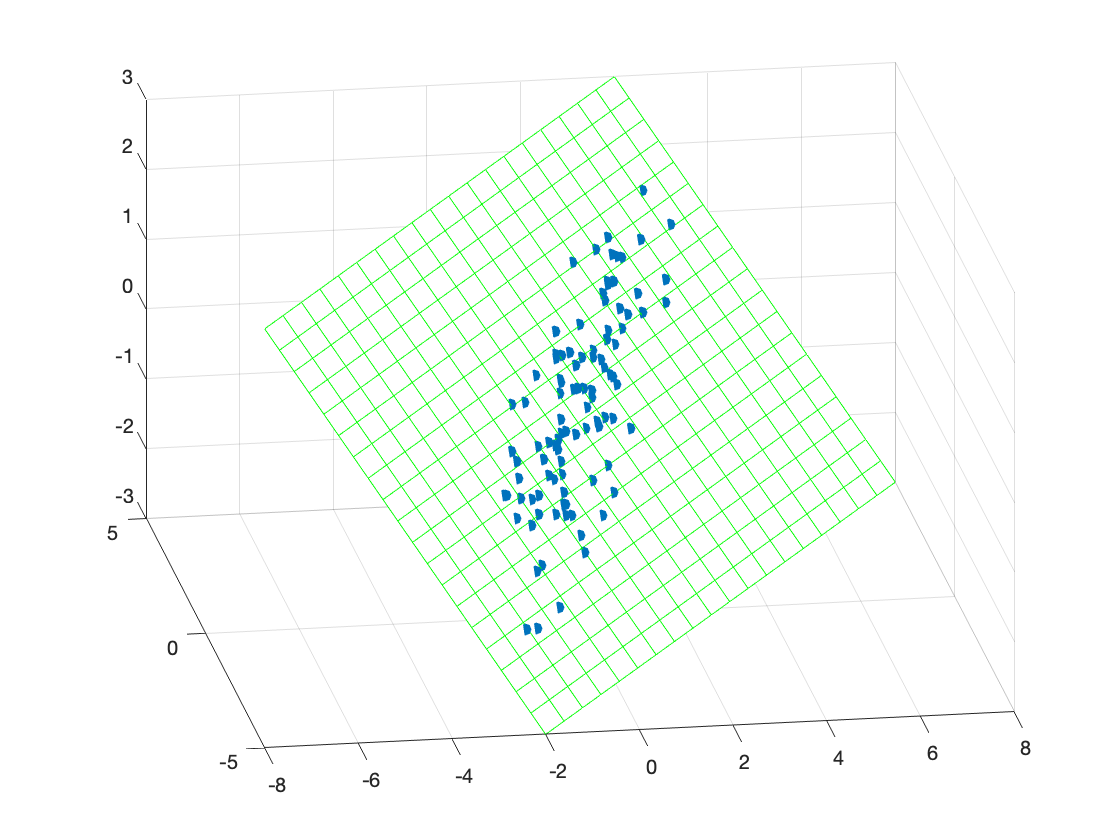

figure
s=linspace(-5,5,20);
t=linspace(-3,3,20);
[S,T]=meshgrid(s,t);
X=S-T;
Y=S;
Z=T;
mesh(X,Y,Z,'EdgeColor','g')
hold on
A=[1 0 2;1 1 3;0 1 1];
pts=1-2*rand(3,100);
Tpts=A*pts;
scatter3(Tpts(1,:),Tpts(2,:),Tpts(3,:),'filled')
view(-9,29)
hold off

Our matrix sent all of our random points to the plane $a-b+c=0$. Rotate the image to verify this statement.

# Example #2

Find a cubic polynomial that passes through each of the points $(1,3)$, $(2,-2)$, $(3,-5)$, and $(4,0)$.

**Solution:** A cubic polynomial has the form


$$y=a_0+a_1x+a_2x^2+a_3x^3$$


Now, let's substitute each of our four points.


$$(x,y)=(1,3)\qquad\longrightarrow\qquad 3=a_0+a_1+a_2+a_3$$



$$(x,y)=(2,-2)\qquad\longrightarrow\qquad -2=a_0+2a_1+4a_2+8a_3$$



$$(x,y)=(3,-5)\qquad\longrightarrow\qquad -5=a_0+3a_1+9a_2+27a_3$$



$$(x,y)=(4,0)\qquad\longrightarrow\qquad 0=a_0+4a_1+16a_2+64a_3$$


Therefore, our system of equations is:


$$\begin{array}{rcl}
a_0+a_1+a_2+a_3&=&3\\
a_0+2a_1+4a_2+8a_3&=&-2\\
a_0+3a_1+9a_2+27a_3&=&-5\\
a_0+4a_1+16a_2+64a_3&=&0
\end{array}$$


Our augmented matrix is:


$$\pmatrix{1 & 1 & 1 & 1 & 3\cr 1 & 2 & 4 & 8 & -2\cr 1 & 3 & 9 & 27 & -5\cr1 & 4 & 16 & 64 & 0}$$


Let's enter this in Matlab and use the rref command to put it in reduced row echelon form.

A=[1 1 1 1 3;1 2 4 8 -2;1 3 9 27 -5;1 4 16 64 0];
rref(A)

ans =      1     0     0     0     4
     0     1     0     0     3
     0     0     1     0    -5
     0     0     0     1     1


Therefore, we have a pivot in each of the first four columns and no free variables.


$$\begin{array}{c}
\matrix{a_0 &\ \,\,a_1 &\ \,a_2 &\ \ a_3 & ~~~}\\
\pmatrix{[1] & \ 0 & \ 0 & \ 0 & \ 4\cr 0 & \ [1] &  \ 0 & \ 0 & \ 3\cr 0 & \ 0 & \ [1] &\  0 & -5\cr 0 & \ 0 & \ 0 & \ [1] & \ 1}\\
\matrix{p &\ \ p &\ \ p &\ \ p&~~~}
\end{array}$$


Therefore,


$$\begin{array}{rcl}
a_0&=&4\\
a_1&=&3\\
a_2&=&-5\\
a_3&=&1
\end{array}$$


Substituting these values into the polynomial, we get:


$$\begin{array}{rcl}
y&=&a_0+a_1x+a_2x^2+a_3x^3\\
y&=&4+3x-5x^2+x^3
\end{array}$$


Now, is this correct?

# Elementwise Operators

Before we can sketch the polynomial, we must first learn how Matlab deals with vectors. First, a row vector. Note that we separate each entry with a comma.

[1,2,3]

ans =      1     2     3


But we can also separate each entry with a space.

[1,2,3]

ans =      1     2     3


What happens when we multiply a vector by a scalar (a number)?

5*[1,2,3]

ans =      5    10    15


It multiplies each entry by the number 5. What happens when we divide a vector by a number?

[2,4,6]/2

ans =      1     2     3


It divides each number by a scalar. What happens when we add two vectors of the same size?

[1,2,3]+[4,5,6]

ans =      5     7     9


It simply adds the 1 and the 4, the 2 and the 5, and the 3 and the 6. What happens when we subtract two vectors?

[5,6,7]-[2,3,1]

ans =      3     3     6


It simply subtracts the 5 and the 2, the 6 and the 3, and the 7 and the 1. Now, what happens when we try to multiply two vectors? If we enter [1,2,3]*[4,5,6] (try it), we get an error message because this is not possible. But, what if we just want to multiply the corresponding elements? The answer is we use what is known as an "elementwise" operator. Note how we put a period before the times sign, which we will do for all "elementwise" operators.

[1,2,3].*[4,5,6]

ans =      4    10    18


Matlab does an element by element multiplication, taking the product of 1 and 4, 2 and 5, and 3 and 6. This also works for division (note the period again).

[4,8,12]./[2,4,6]

ans =      2     2     2


Matlab does an element by element division, taking the quotient of 4 and 2, 8 and 4, and 12 and 6. What if we want to raise each element of a vector to a power (note the period again)?

[1,2,3].^2

ans =      1     4     9


Matlab does an element by element power, raising 1 to the second power, 4 to the second power, and 3 to the second power.

# Visualizing Our Polynomial

Now we will see why we introduced the elementwise operators. Let's generate 5 equally space numbers between 0 and 5.

x=linspace(0,2,5)

x =          0    0.5000    1.0000    1.5000    2.0000


Now, let's square each element and store it in the variable y.

y=x.^2

y =          0    0.2500    1.0000    2.2500    4.0000


Now, let's plot y versus x.

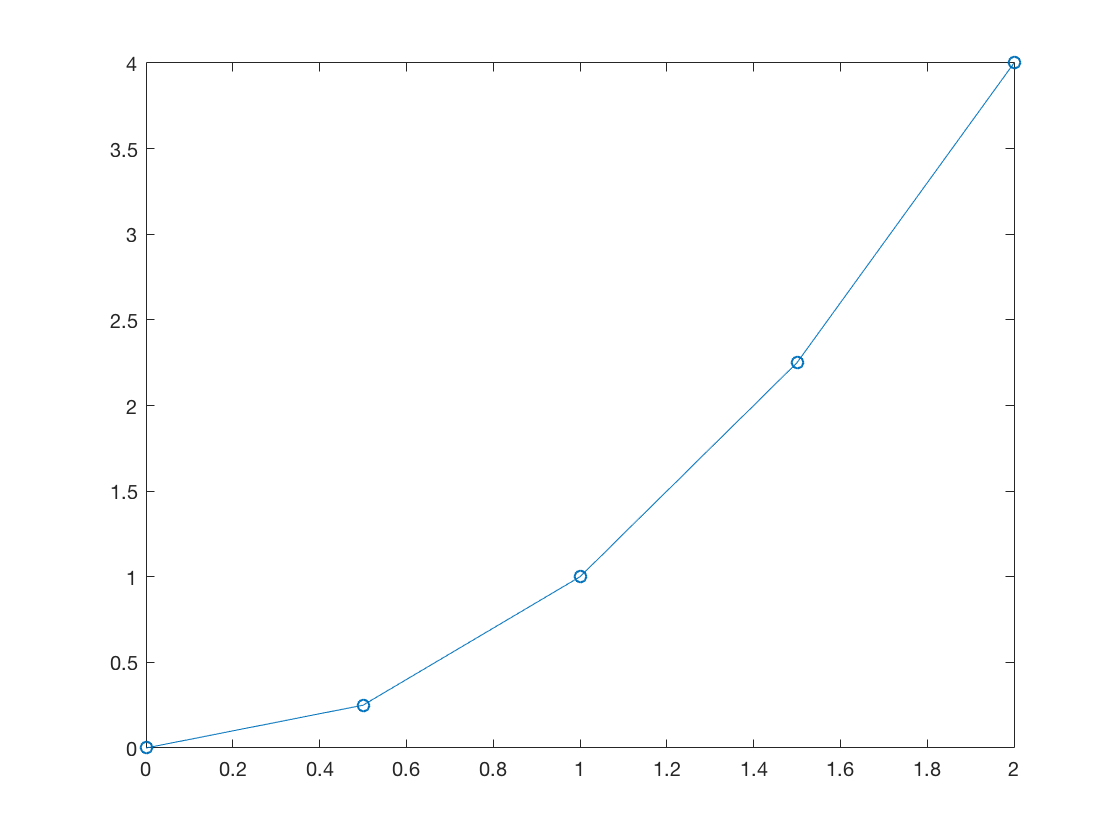

plot(x,y,'o-')

Note that Matlab plots the points x and y, and connects each consecutive pairs of points with a line segment. Because we plotted so few points, the graph is a bit jagged, so let's plot more points. This time we won't show the points, but try plot(x,y,'o-') if you want to see them.

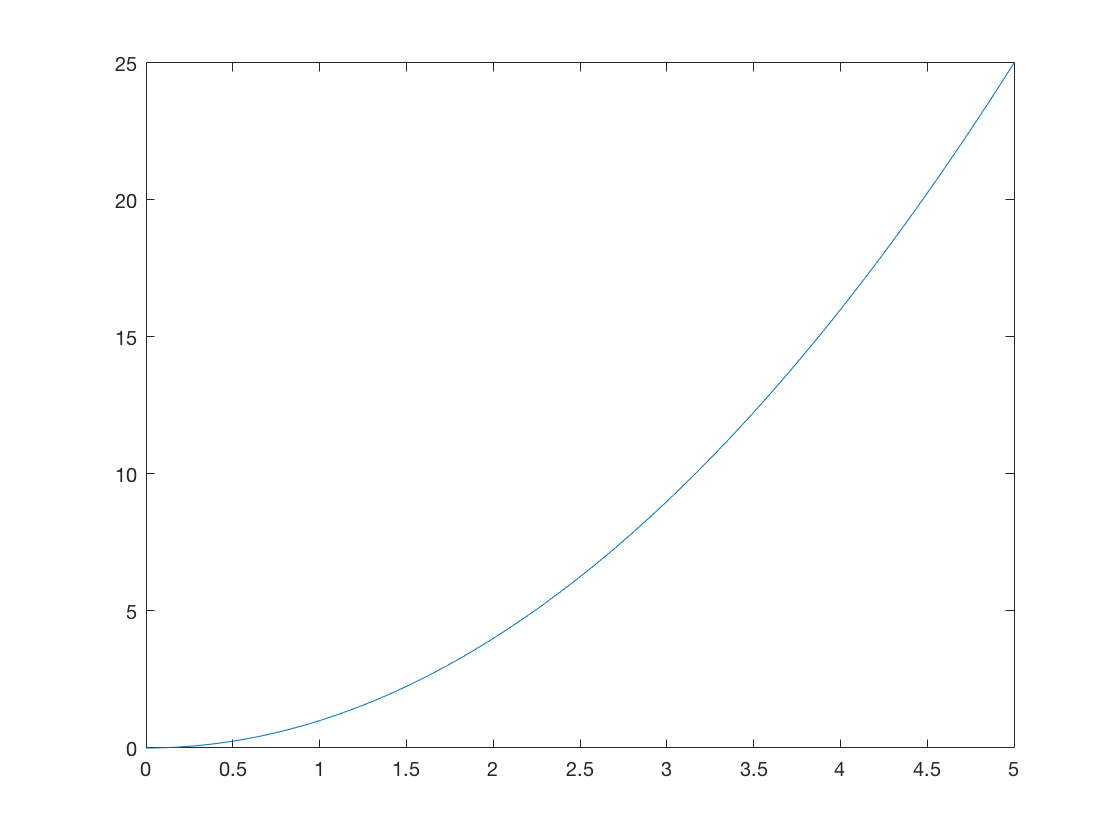

x=linspace(0,5,200);
y=x.^2;
plot(x,y)

Ah! Nice and smooth, and this is part of the parabola $y=x^2$ that we are quite familiar with. Now we are ready to plot the polynomial we found in Example #2 above.

# Visualizing Our Answer

In our work in Example #2, we claim that the cubic polynomial 


$$y=4+3x-5x^2+x^3$$


will pass through the points $(1,3)$, $(2,-2)$, $(3,-5)$, and $(4,0)$. Because teh $x$-values of these points are 1, 2, 3, and 4, let's plot the curve over the interval $0\le x\le 5$.

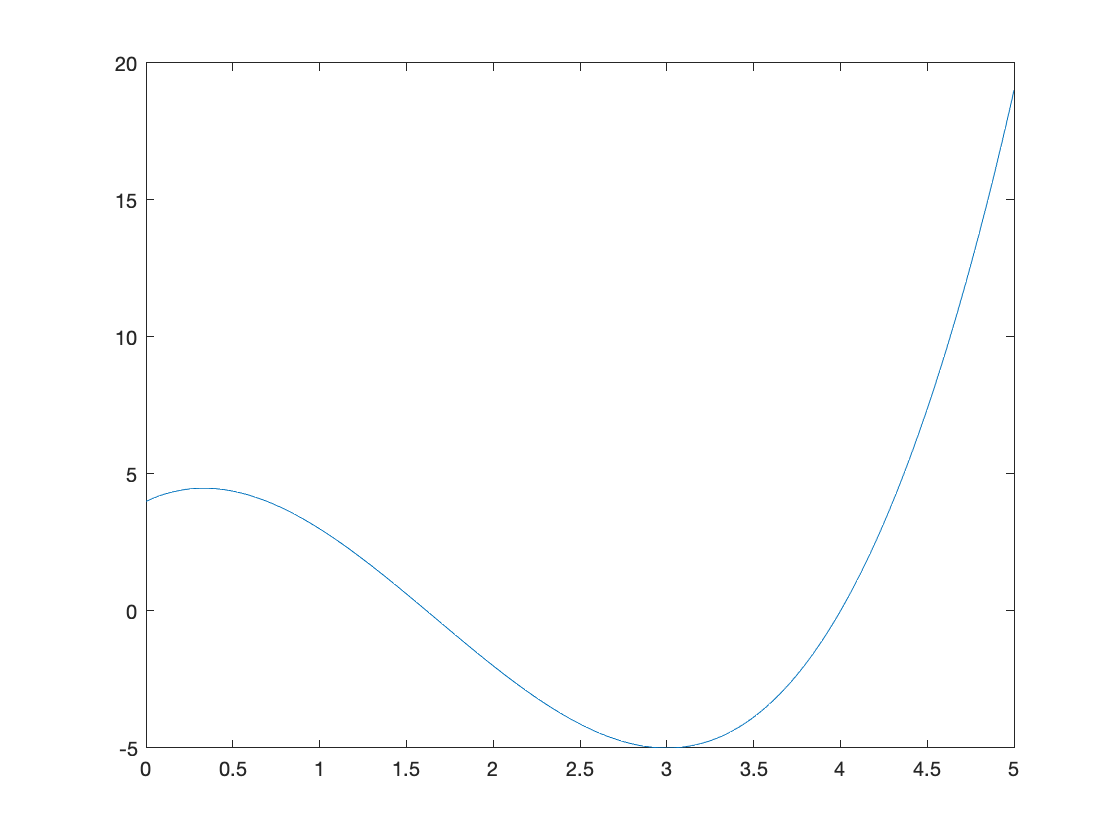

x=linspace(0,5,200);
y=4+3*x-5*x.^2+x.^3;
plot(x,y)

Now, does it pass through the points $(1,3)$, $(2,-2)$, $(3,-5)$, and $(4,0)$? Let's add these to our image.

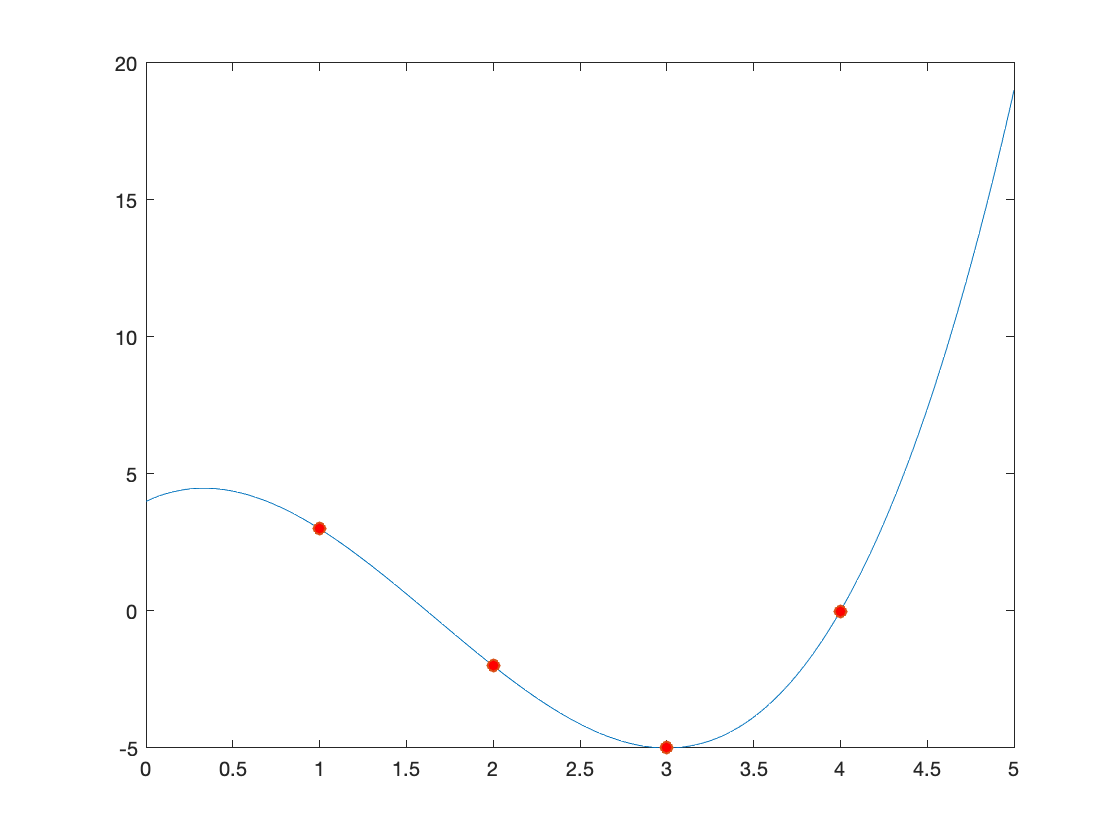

x=linspace(0,5,200);
y=4+3*x-5*x.^2+x.^3;
plot(x,y)
hold on
plot([1,2,3,4],[3,-2,-5,0],'o','MarkerFaceColor','r')
hold off

They do lie on our cubic polynomial, so we have done the problem correctly. Let's prettify our image.

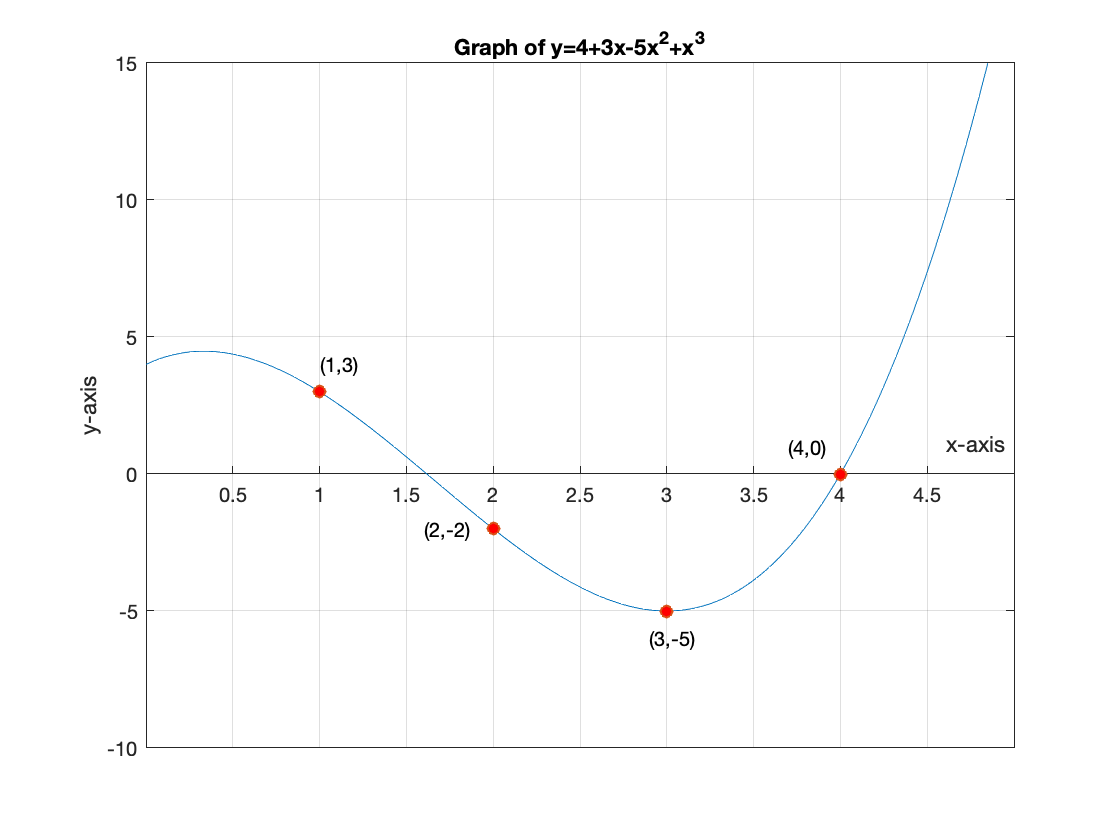

x=linspace(0,5,200);
y=4+3*x-5*x.^2+x.^3;
plot(x,y)
hold on
plot([1,2,3,4],[3,-2,-5,0],'o','MarkerFaceColor','r')
axis([0,5,-10,15])
grid on
ax=gca;
ax.XAxisLocation='origin';
xlabel('x-axis')
ylabel('y-axis')
title('Graph of y=4+3x-5x^2+x^3')
text(1,4,'(1,3)')
text(1.6,-2,'(2,-2)')
text(2.9,-6,'(3,-5)')
text(3.7,1,'(4,0)')
hold off

Pretty! We're done. :-)